# 读写操作篇

数据是从哪里来的？

文件是不同软件数据传输的桥梁，matlab它有自己的数据储存文件.mat，但是在其他软件是不能使用的，同样在其他软件有matlab不能使用的储存文件，所以为了在软件中都能进行读取和保存，我们通常会将数据保存为文件，常见的有txt文件、csv文件、excel文件等等。

文件分为二进制文件以及文本文件，在这里我只讲解**文本文件**的读写操作。

## **文本文件的读取**

matlab有很多读函数，要学会根据不同的需要去选择不同函数，在这里我讲解几个最常用的。

读取一切txt、csv文件：**textscan**，还有其他一些更为简单的函数如csvread、dlmread等等，但是这些函数的适用范围实在太小了，稍微复杂一点的数据就不能读取，但是textscan不一样，textscan函数是matlab读取文本文件的一大利器，可以说学会textscan函数就可以读取出任何文本文件。

读取excel文件：xlsread，后面会简单介绍。

### textscan

textscan的用法如下：

`data = textscan(文件句柄/字符串, 提取格式[, 参数1, 值1, ...]);`

`其中[]括号里的不是必填的，不填则取默认值。`

`文件句柄接下来会讲。`

`提取格式如整数%d，浮点数%f，字符串%s，还有很多格式，具体查看文档。`

`返回的data是一个元胞数组`

#### `textscan参数`

`下面我讲几个最为常用的参数使用：`

`1、delimiter`

`分隔符`

% 空格区分的字符串
str = '1 嘻嘻 3';
% 提取格式，整数字符串整数
formatSpec = '%d%s%d';
data = textscan(str, formatSpec)

data = 1×3 cell 数组
    {[1]}    {1×1 cell}    {[3]}


data{2}

ans = 1×1 cell 数组
    {'嘻嘻'}


% 逗号区分的字符串
str = '1,嘻嘻,3';
formatSpec = '%d%s%d';
data = textscan(str, formatSpec)

data = 1×3 cell 数组
    {[1]}    {1×1 cell}    {0×1 int32}


data{2}

ans = 1×1 cell 数组
    {',嘻嘻,3'}


% 结果并不是我们想要的
% 第一个%d匹配了1，而%s匹配了,嘻嘻,3，最后一个%d没有任何东西匹配。
% 为什么空格可以，而逗号就不能呢。这是因为textscan的默认分隔符就是空格。

% 现在我们改为逗号
delimiter = ',';
str = '1,嘻嘻,3';
formatSpec = '%d%s%d';
data = textscan(str, formatSpec,'delimiter',delimiter)

data = 1×3 cell 数组
    {[1]}    {1×1 cell}    {[3]}


data{2}

ans = 1×1 cell 数组
    {'嘻嘻'}


% 成功了！

% 再看看下面的情况，有多种分隔符
str = '1;2 3-4,5??6';
formatSpec = '%d%d%d%d%d%d';
% 不同分隔符用元胞数组包含
delimiter = {',','-',' ',';','??'};
data = textscan(str,formatSpec,'delimiter',delimiter)

data = 1×6 cell 数组
    {[1]}    {[2]}    {[3]}    {[4]}    {[5]}    {[6]}


2、collectOutput

合并相邻为数字的元胞数组

str = '1,2,3,4,5,6';
formatSpec = '%d%d%s%d%d%d';
delimiter = ',';
data = textscan(str,formatSpec,'delimiter',delimiter,'collectOutput',true)

data = 1×3 cell 数组
    {1×2 int32}    {1×1 cell}    {1×3 int32}


% 可以看到输出不像之前那样返回1*6的元胞数组，而是返回了1*3的元胞数组。

3、EmptyValue

缺失值处理，%d为0，%s为空，%f为nan

str = '1,,3,4,,6';
formatSpec = '%d%f%d%d%d%d';
delimiter = ',';
data = textscan(str,formatSpec,'delimiter',delimiter)

data = 1×6 cell 数组
    {[1]}    {[NaN]}    {[3]}    {[4]}    {[0]}    {[6]}


% 改变%f的缺失值处理。
str = '1,,3,4,,6';
formatSpec = '%d%f%d%d%d%d';
delimiter = ',';
% 将%f的缺失值变为0
emptyvalue = 0;
data = textscan(str,formatSpec,'delimiter',delimiter,'EmptyValue',emptyvalue)

data = 1×6 cell 数组
    {[1]}    {[0]}    {[3]}    {[4]}    {[0]}    {[6]}


4、TreatAsEmpty

将指定字符视为空

str = '1,B,3,A,5,6,7,8';
formatSpec = '%d%d%d%d';
delimiter = ',';
data = textscan(str,formatSpec,'delimiter',delimiter)

data = 1×4 cell 数组
    {[1]}    {0×1 int32}    {0×1 int32}    {0×1 int32}


% 将B和A都当作空值处理
TreatAsEmpty = {'B','A'};
data = textscan(str,formatSpec,'delimiter',delimiter,'TreatAsEmpty',TreatAsEmpty)

data = 1×4 cell 数组
    {[1]}    {[0]}    {[3]}    {[0]}


5、HeaderLines

跳过指定行后开始读取

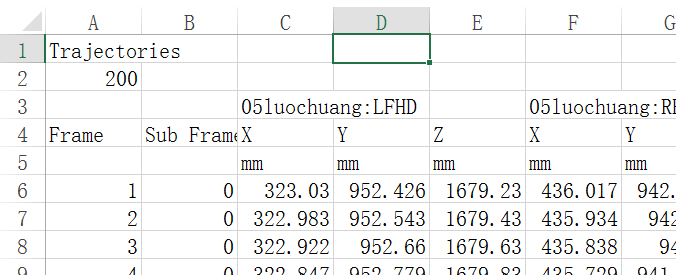

如上图，第6行开始才是我想要的数据，直接读取肯定是不行的，此时我们可以用HeaderLines跳过前5行开始读取。

data = textscan(文件句柄,格式,'HeaderLines',5);

#### 实战

上面的例子我都是通过字符串进行讲解的，现在我们开始读取真正的文件吧。

在此之前我们来认识一下什么是文件句柄。

文件句柄就是文件的标识符，通过这个句柄就可以对文件进行读写操作。

如何获取文件句柄呢？

f = fopen(文件名,读写权限); 

有下面几种，默认是'r'，表示读，'w'表示清空后写，'a'表示添加。

fopen打开文件并获取句柄。然后开始对文件进行处理。

处理完最后需要关闭文件fclose(文件句柄);

现在我有一个文件。我要读取文件的数据

第一步，打开文件

f = fopen('4km.csv');

第二步，编写提取规则。

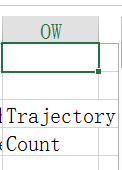

打开文件，可以看出有OW列，换算一下就是413列。那我是不是要自己写413个%f呢，这有点夸张了，而且也数不清。此时可以用repmat函数，该函数可以重复数组。

% 对'%f'进行1行，413列的复制。
formatSpec = repmat('%f',[1,413])

formatSpec = '%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f'

数据是从第6行开始的，所以headerlines为5。

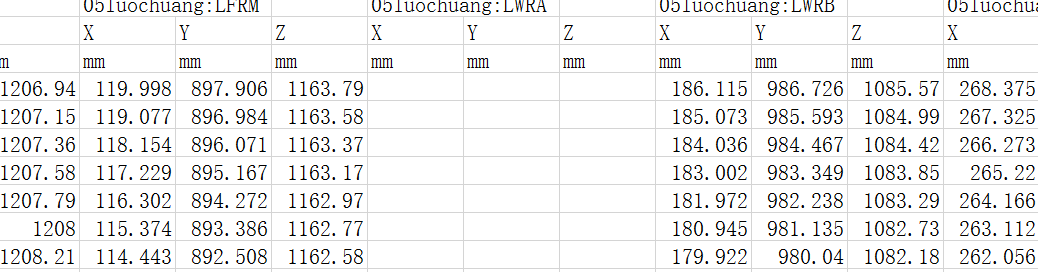

有些数据是空的，如果要将空的值变为0，可以设置EmptyValue为0。

因为全都是数字，所以我可以使用collectOutput合并元胞数组。

csv文件是以逗号为分割符的，所以`delimiter设置为','`

最后一步，关闭文件

fclose(f);

经过上面分析，最后可以写出：

我们再看看下一种情况。

打开，我们可以看到数据是分为两节的，用上面的方法只能读取出第一节，当读取到第245行时，不符合提取规则了，此时会停止读取。此时文件指针停在第245行。

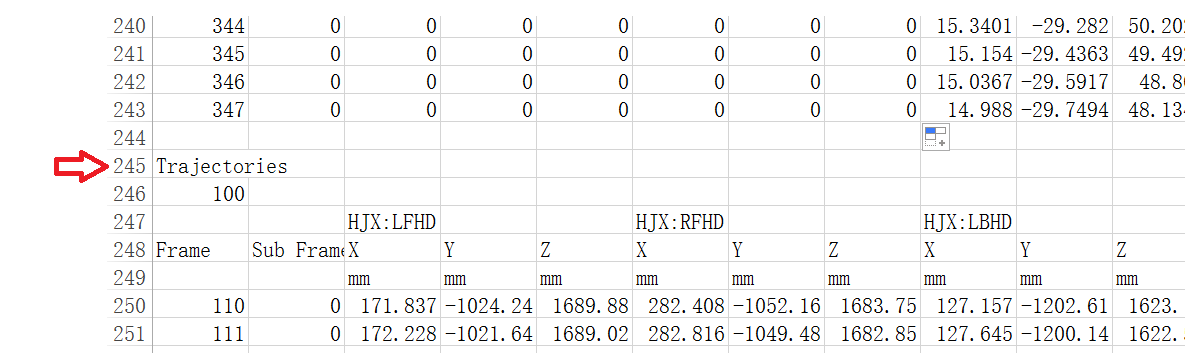

观察文件可以发现，上下两节的数据规律是一样的，不同在于列数不同。

所以可以写成下面的方式

### `读取excel文件`

`[num,txt,raw] = xlsread(filename)`

`num为数字数据（使用矩阵储存）、txt为字符串数据（元胞数组储存）、raw为混合数据（使用元胞数组储存）`

### `批量读取`

`这个技巧真的非常非常重要，因为一般情况下你是不会只有一个文件需要读取的，比如你是一个学生，做了很多实验，这时候你就有大量的实验数据文件了，如果手动去一个一个的读取，将会耗费非常大的工夫，所以在这里我们来学习一下批量操作的方法。`

`需要使用到的是dir函数和迭代，迭代必须要用函数实现。`

`提取出指定路径下的所有文件`

`提取出自己需要的文件进行处理`

## `文本文件的写入`

`文件写主要用到一个函数fprintf，然后一行一行的将数据写入文件即可。`

`fprintf(文件句柄, 格式, 数据);`

`不传文件句柄就是打印到命令行窗口。`

`fprintf(格式, 数据);`

`一个一个匹配`

`fprintf('%d%d\n', [1,2],3,4);`

`fprintf('%d%d\n', [1,2,3,4]);`

`fprintf('%d%d\n', [1,2;3,4]);`